# **ACM/IDS 104 - Problem Set 5 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

## Problem 1 (10 points) Application of  Projections to Approximation

In Problem 4 of PS4, we saw that even higher degree interpolating polynomials may not be accurate approximations to complex functions. We have the function:


$$f(x) = \frac{\cos x}{\cosh x}, \,\,\,\,\,\mbox{on } [-a,a],\,\,\,\,\, a=5$$


Let us recall how this function looks like and how its interpolating polynomials of degree $(n-1)$ for $n = 3,5,10,15$ behave:

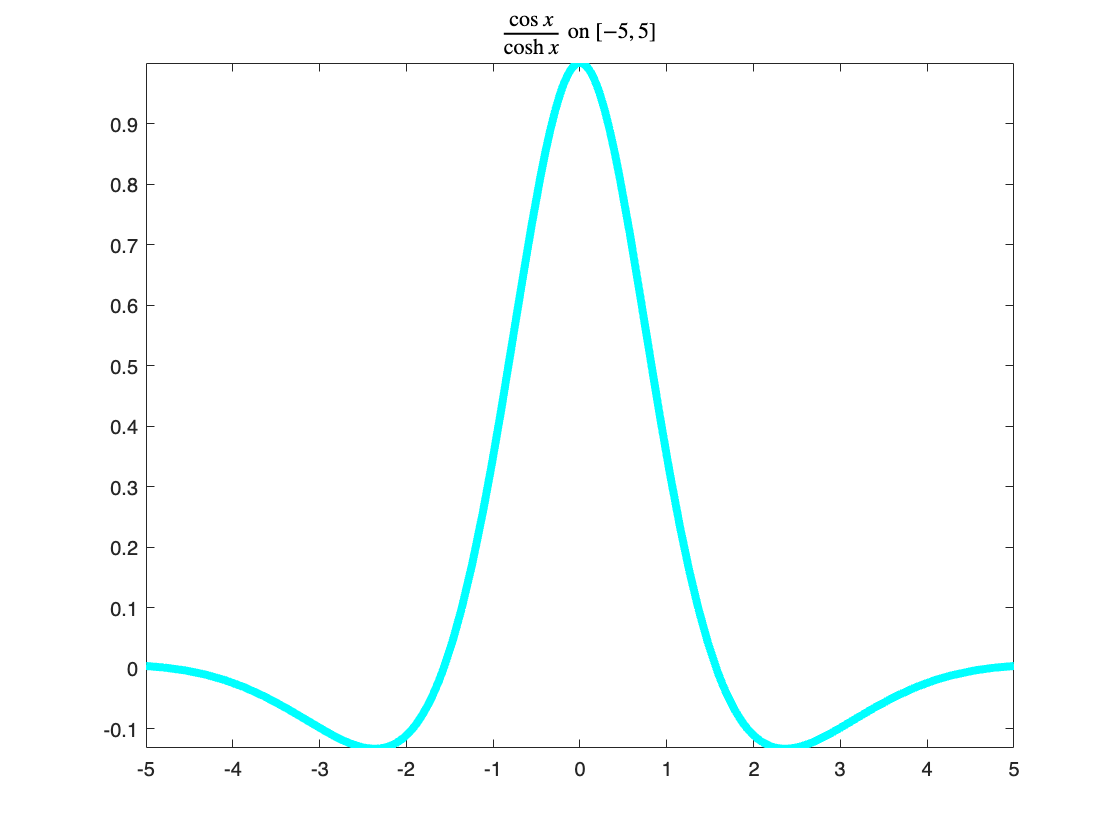

%{
Setup
%}
f = @(x) cos(x)./cosh(x); % our function
a = 5; % setting the value of a
n = [3 5 10 15]; % setting the number of points
sub = 1; % subplot index

%{
How f(x) looks like on [-5, 5]
%}
figure;
fplot(f, [-a, a], "-c", "lineWidth", 4);
title("$\frac{\cos{x}}{\cosh{x}}$ on $[-5, 5]$","Interpreter","latex");

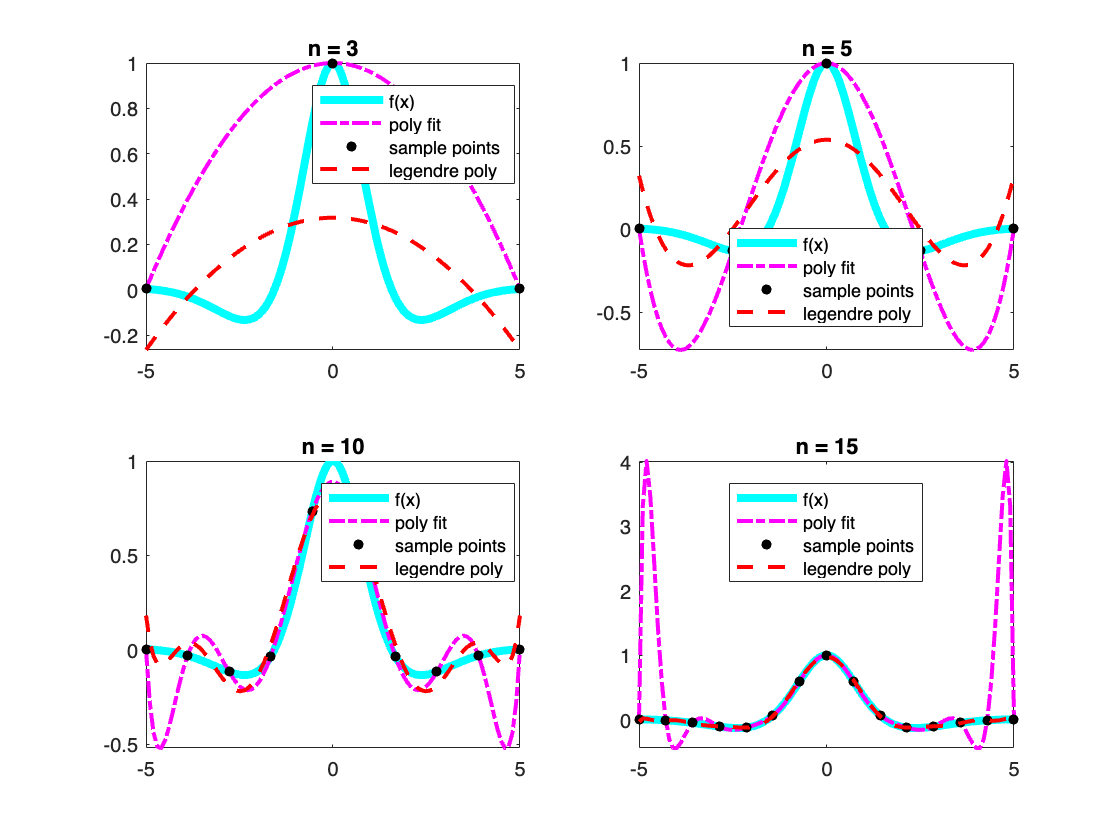


%{
Read the discussion below and complete the code
%}
figure;
for ival = a
    for degree = n-1
        %{
        INTERPOLATING POLYNOMIALS -- no changes needed
        -> Select degree+1 points in the interval
        -> Evaluate f(x) on these points
        -> Find the polynomial coefficients
        %}
        pts = ones(degree+1, 2); % initializing the points
        pts(:, 1) = linspace(-ival, ival, degree+1); % setting the x-values
        for i = 1 : degree+1
            pts(i, 2) = f(pts(i, 1)); % evaluating cos(x) / cosh(x)            
        end
        coeffs = polyfit(pts(:, 1), pts(:, 2), degree); % coefficients
        %{
        ORTHOGONAL PROJECTIONS -- TODO
        -> Get transformed Legendre polynomials
        -> Find alpha_k using L^2 inner product
        -> Evaluate alpha_k*Q_k
        %}

        a0 = -ival;
        b = ival;
        p_star = @(x) 0;
        for i = 0:degree
            leg_poly = @(y) legendreP(i, (2*y - b - a0)/(b-a0));
            leg_poly_norm = integral(@(y) leg_poly(y) .* leg_poly(y), a0, b);
            inner_prod = integral(@(y) f(y) .* leg_poly(y), a0, b);
            alpha_i = inner_prod/leg_poly_norm;
            p_star = @(x) p_star(x) + alpha_i .* leg_poly(x);
        end
        %-> Evaluate alpha_k*Q_k for all points

        points = linspace(-ival, ival, 100);
        p_star_eval = p_star(points);

        
        %{ 
        PLOTTING
        Plot f(x), the sampled points, interpolating and approximating
        polynomials
        Please use different colors and linestyles
        %}
        subplot(2, 2, sub);
        fplot(f, [-ival, ival], "-c", "lineWidth", 4);
        hold on
        interpoints = linspace(-ival, ival);
        p = polyval(coeffs, interpoints); % evaluating coeffs in interval
        plot(interpoints, p, "-.m", "lineWidth", 2);
        plot(pts(:, 1), pts(:, 2), "ok", "MarkerSize", 2, "lineWidth", 3);

        % added this
        plot(points, p_star_eval, "--", "lineWidth", 2, 'Color', 'r');

        title(strcat("n = ", int2str(degree+1)));
        sub = sub + 1; % increase subplot index
        legend('f(x)', 'poly fit', 'sample points', 'legendre poly', "location", "best");
    end
end

Now, instead of interpolating polynomials, let us approximate $f(x)$ by its orthogonal projection onto the inner space $\mathcal{P}^{(n-1)}_{[-a,a]}$ of polynomials on $[-a,a]$, equipped with the $L^2$ inner product:


$$f(x)\approx p(x)=\mathrm{pr}_{\mathcal{P}^{(n-1)}_{[-a,a]}}f(x)$$


Recall (Lecture 10) that $p(x)$ is the closest (in the $L^2$ sense) polynomial to $f(x)$ in $\mathcal{P}^{(n-1)}_{[-a,a]}$, i.e.


$$p(x)=\arg\min_{q\in\mathcal{P}^{(n-1)}_{[-a,a]}}\|f(x)-q(x)\|$$


We know that the transformed Legendre polynomials $\widetilde{Q}_0(x),\cdots,\widetilde{Q}_{n-1}(x)$ form an orthogonal basis of $\mathcal{P}^{(n-1)}_{[-a,a]}$, and, therefore:


$$p(x)=\sum_{k=0}^{n-1}\alpha_k\widetilde{Q}_k(x)$$


where $\alpha_k$ are the coordinates of $p(x)$ in that basis.

Modify the above code to find the approximating polynomials as well. Plot each approximating polynomial on its corresponding subplot. Useful functions for this problem:


$$\texttt{legendreP(), integral()}$$
